## Parameters

on_GPU = false;
T = 40; % sec
N = 200; % number of neurons 200
input_Hz = 50; % Hz
conn_prob_input2E = 0.1; % a.u.
conn_strength_input2E = 1; % a.u.
conn_prob_E2E = 0.25; % a.u.
conn_strength_E2E = 1; % a.u.
STDP_learning_rate_E2E = 1; % a.u. (STDP)

plasticity_type = "rbSTDP";

plot_synapses = false;
plot_Vm = false;
plot_spikes = false;
plot_refractoriness = false;
plot_weights = true;
plot_Hz = true;
plot_stimulation = true;
plot_STDP_traces = false;
plot_resource_pool = true;
plot_digraph = true;
plot_non_potentiable = true;
plot_dependence = false;

## Run a single EI pool with

samples = 8;
pool_single = cell(samples);

parfor n=1:samples
    % Set up
    tic
    pool_single{n} = RB_STDP_EI_pool( ...
        T, ...
        N, ...
        on_GPU, ...
        conn_prob_input2E, ...
        conn_strength_input2E, ...
        conn_prob_E2E, ...
        conn_strength_E2E, ...
        plasticity_type, ...
        plot_synapses, ...
        plot_Vm, ...
        plot_spikes, ...
        plot_refractoriness, ...
        plot_weights, ...
        plot_Hz, ...
        plot_stimulation, ...
        plot_STDP_traces, ...
        plot_resource_pool, ...
        plot_digraph, ...
        plot_non_potentiable, ...
        plot_dependence ...
        );
    pool_single{n}.set_input( ...
        input_Hz ...
        );
    toc
    % Run
    tStart = tic;
    pool_single{n}.run( ...
        false, ... % plot_during
        STDP_learning_rate_E2E ...
        );
    tEnd = toc(tStart);
    fprintf( ...
        'Elapsed time is %d minutes and %f seconds\n', ...
        floor(tEnd/60), ...
        rem(tEnd,60) ...
        );
    % Finish
    tic
    pool_single{n}.finish()
    toc
end

Elapsed time is 1.629960 seconds.
Elapsed time is 2.351408 seconds.
Elapsed time is 2.304920 seconds.
Elapsed time is 2.286490 seconds.
Elapsed time is 2.366423 seconds.
Elapsed time is 2.385247 seconds.
Elapsed time is 2.401128 seconds.
Elapsed time is 2.400787 seconds.
Elapsed time is 181 minutes and 50.345409 seconds
Elapsed time is 0.782899 seconds.
Elapsed time is 185 minutes and 54.210562 seconds
Elapsed time is 0.292041 seconds.
Elapsed time is 190 minutes and 43.420517 seconds
Elapsed time is 0.270299 seconds.
Elapsed time is 197 minutes and 42.173705 seconds
Elapsed time is 0.557343 seconds.
Elapsed time is 200 minutes and 29.225742 seconds
Elapsed time is 0.243865 seconds.
Elapsed time is 221 minutes and 23.998517 seconds
Elapsed time is 0.191990 seconds.
Elapsed time is 225 minutes and 17.048910 seconds
Elapsed time is 0.160603 seconds.
Elapsed time is 226 minutes and 1.301071 seconds
Elapsed time is 0.163209 seconds.


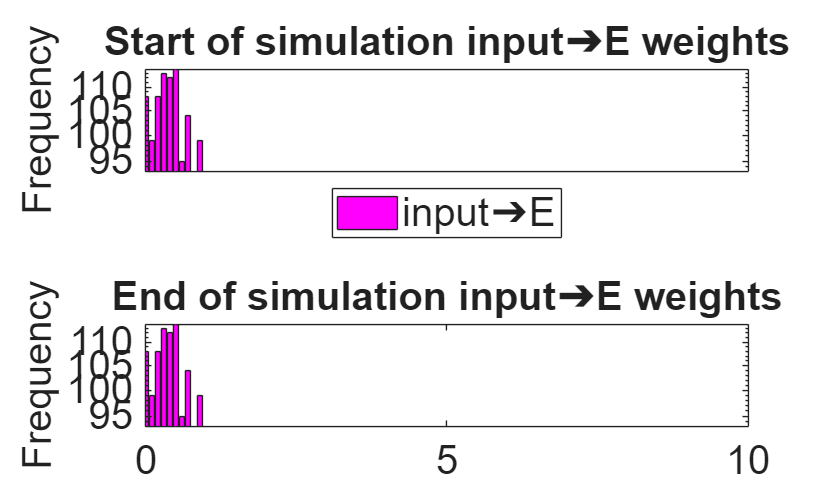

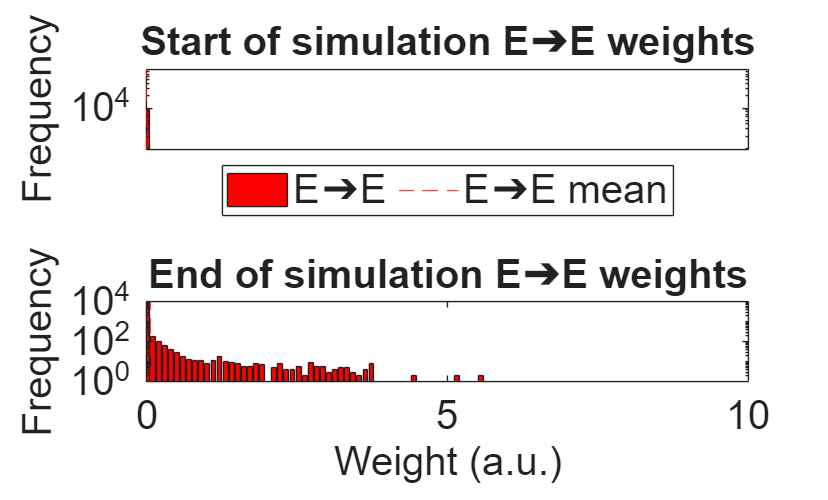

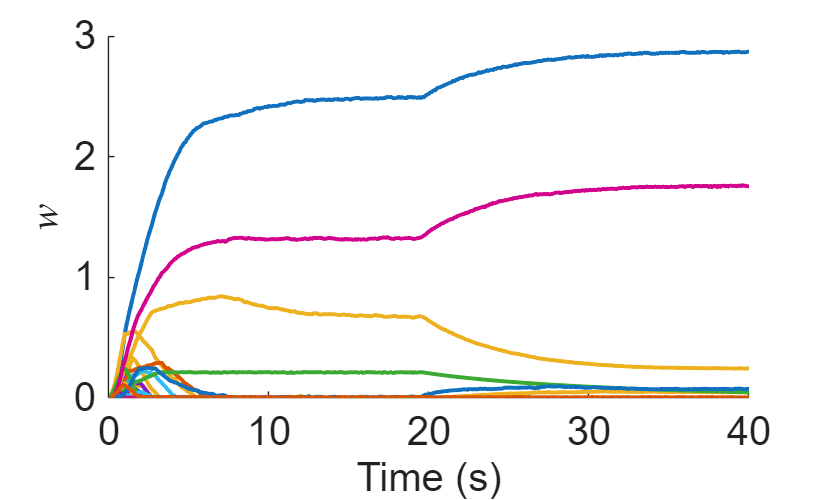

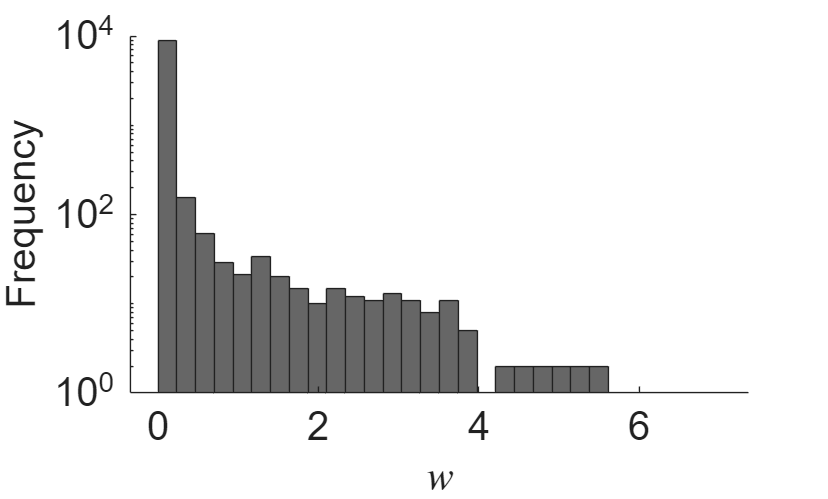

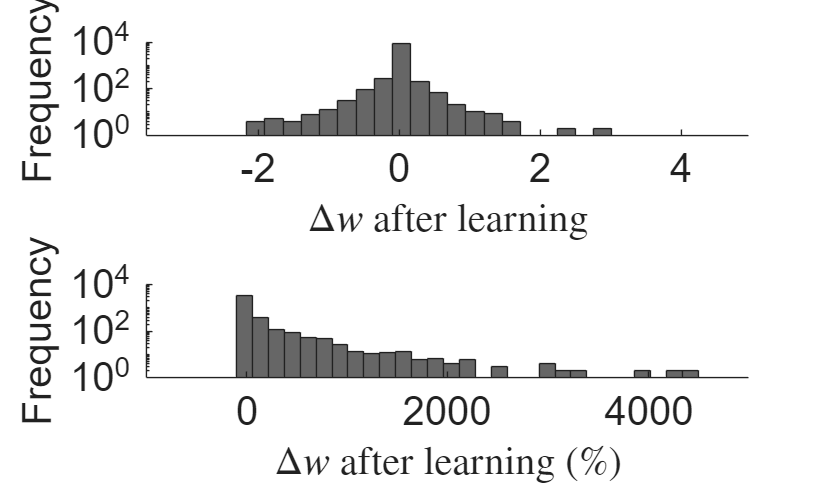

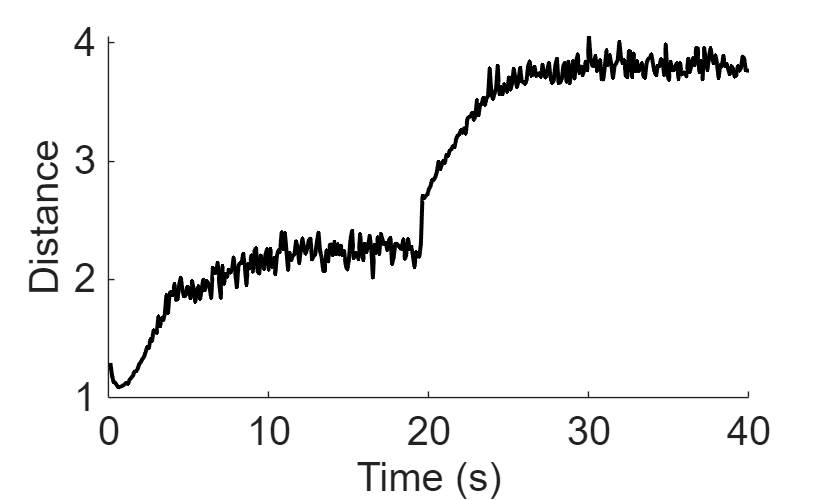

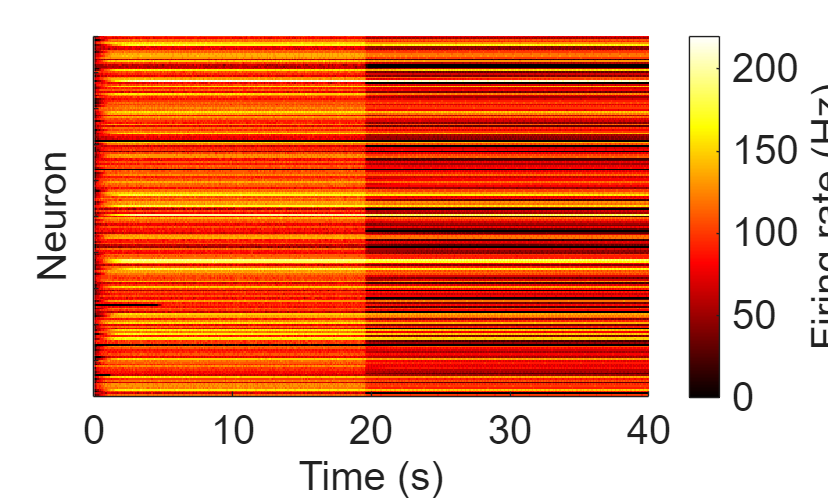

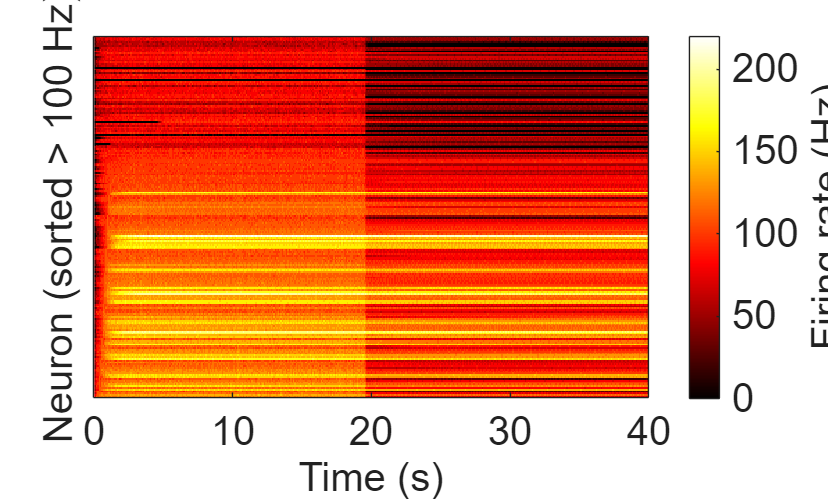

% Plot
tic
pool_single{4}.fontsize = 20;
pool_single{4}.plot( ... % 4
    true ... % export
    )

toc

Elapsed time is 59.656820 seconds.
